**Richardsonextrapolation**

Vid Richardsonextrapolation använder vi, i en iterativ kontext, historisk data för att gissa på framtida integralvärden (genom trapetsregeln).

Exempel extrapolering:

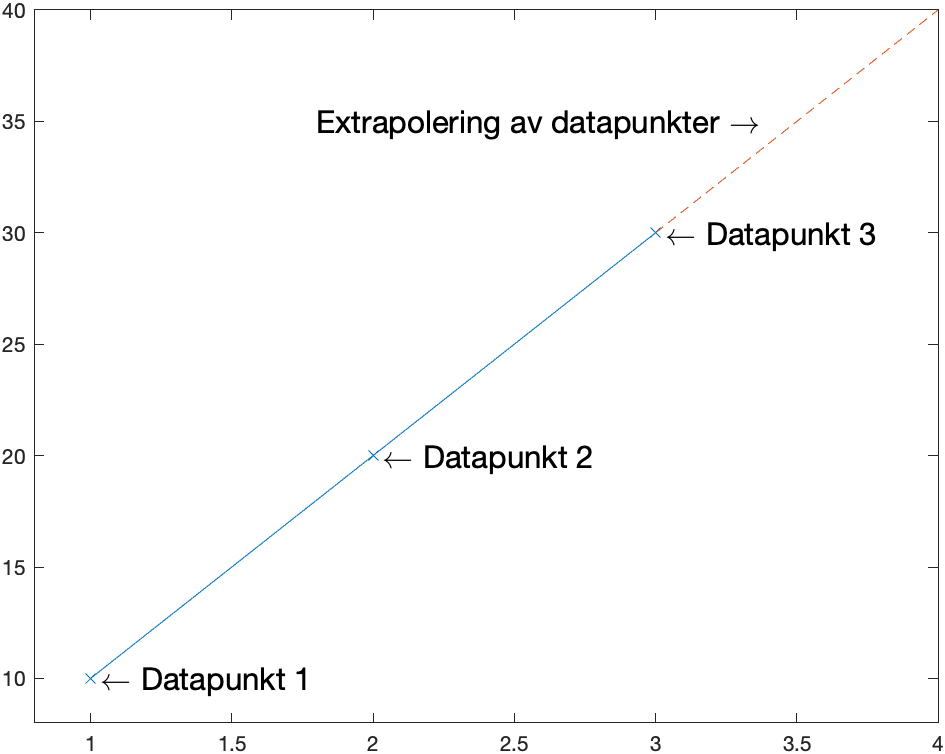

Genom att iterativt kombinera det förra trapetsskattningen med den nya kan en bättre skattning skapas:

Exempel: Beräkna ${\int_0^2 x^2 \;\mathrm{dx}}^{\;}$

Vi börjar med att använda Trapetsregeln med ett intervall:


$$T\left(h=2\right)=h*\frac{\left(f\left(0\right)+f\left(2\right)\right)}{2}=2*\frac{0+4}{2}=4$$


Grafiskt ser trapetsen ut som följer:

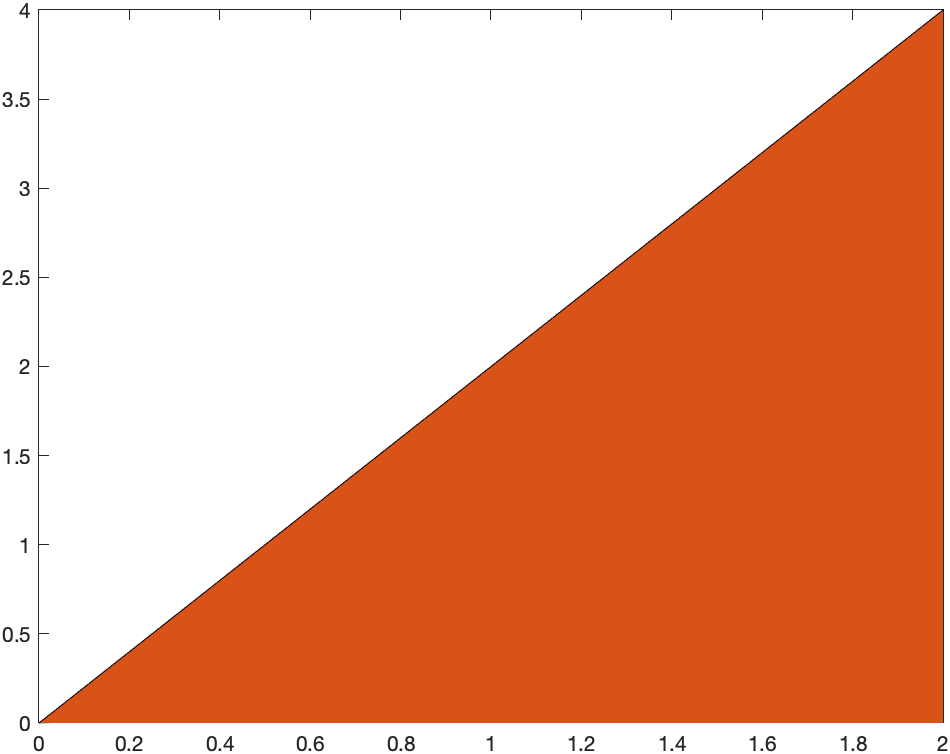

Sedan gör vi samma process med två intervall:


$$T\left(h=1\right)=h*\frac{\left(f\left(0\right)+f\left(2\right)\right)}{2}+h*f\left(1\right)=4+2*1=6$$


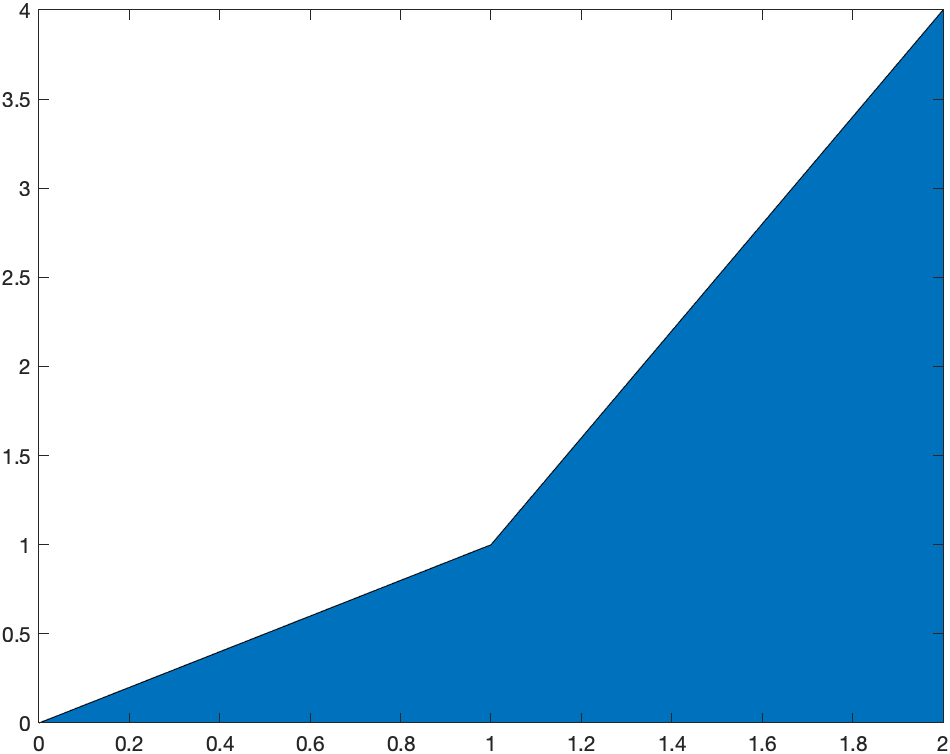

Skillnaden $T\left(h\right)-T\left(2h\right)$ ser ut:

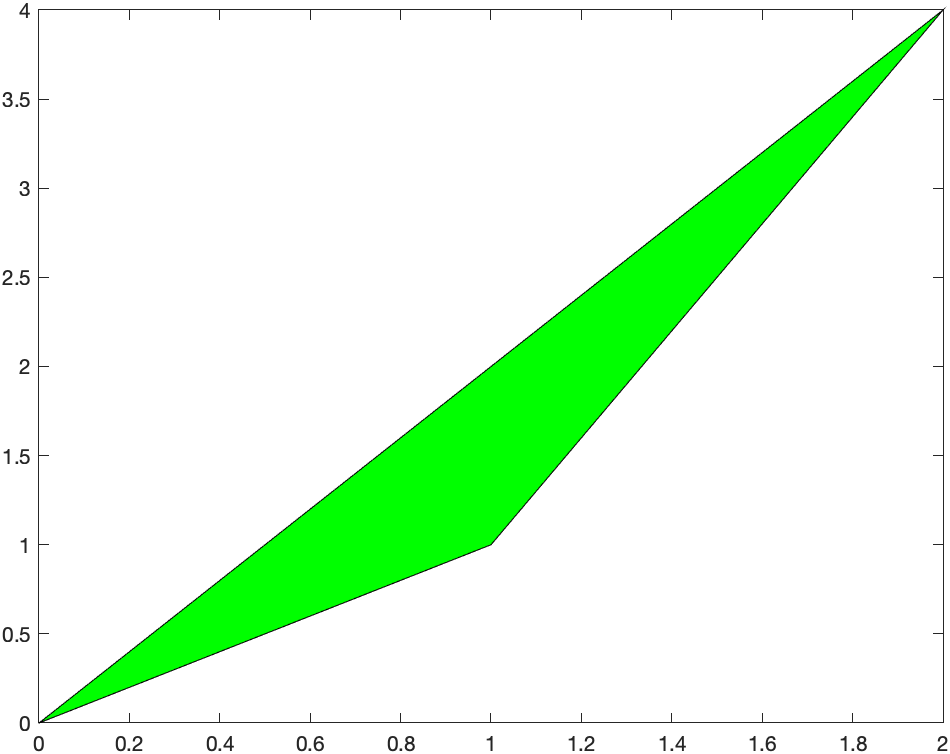

Richardsonextrapolationen säger att vi ska dra av skillnaden $\frac{T\left(h\right)-T\left(2h\right)}{3}\;$från vår skattning, vilket grafiskt kan tolkas som att vi delar vår gröna triangel på 3. 

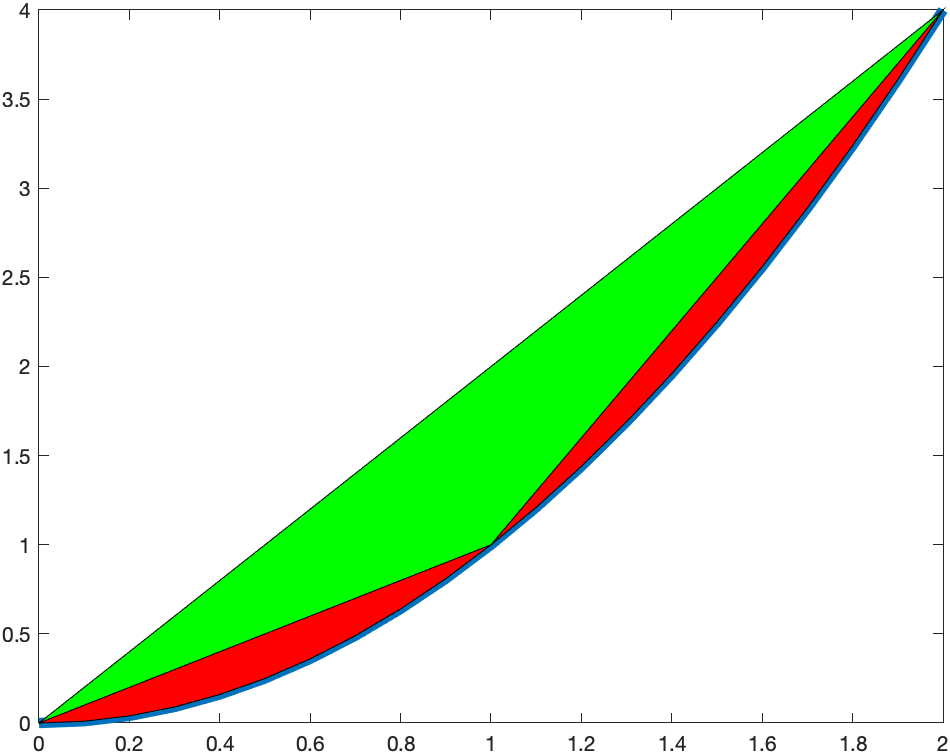

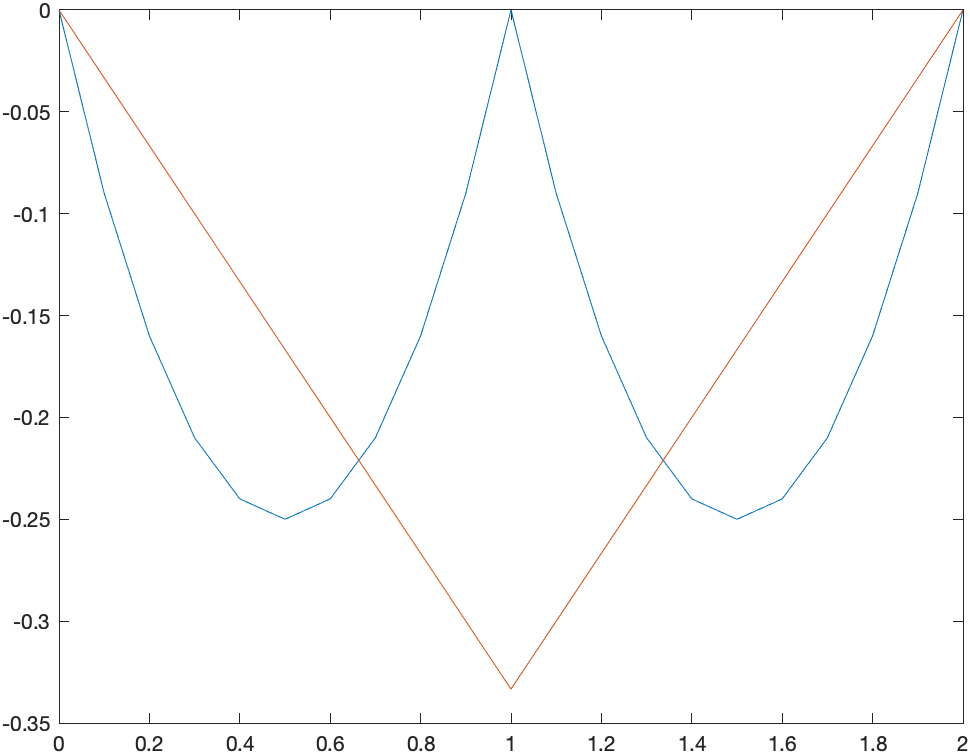

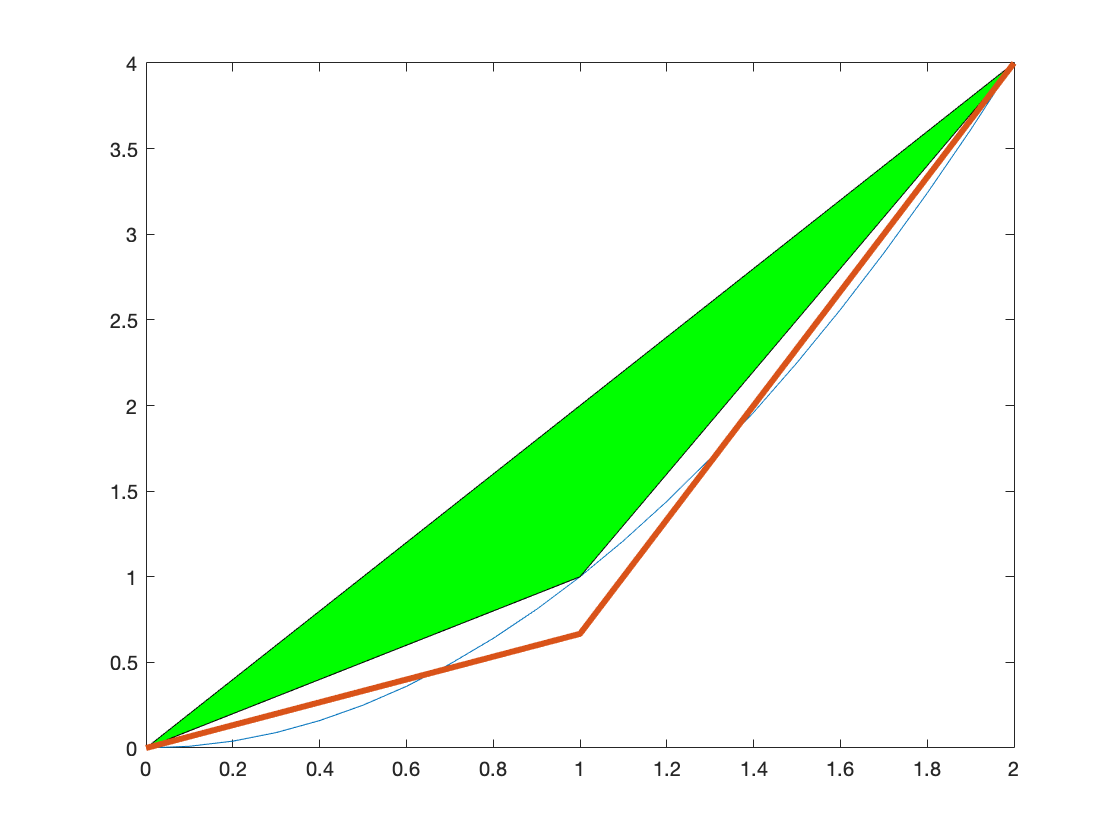

f = @(x) x.^2;
xi = 0:0.1:2;
y1 = interp1([0, 2], [f(0), f(2)], xi);
y2 = interp1([0, 1, 2], [f(0), f(1), f(2)], xi);

%plot(xi, f(xi))
%plot(xi, f(xi), "LineWidth", 5)
%hold on
%patch([0, 2, 1], [0, 4, 1],'green')
%hold off
%patch([0, 1, 1:-0.1:0], [0, 1, f(1:-0.1:0)], "red")
%patch([1, 2, 2:-0.1:1], [1, 4, f(2:-0.1:1)], "red")
%hold off

%plot(xi, f(xi)-y2)
plot(xi, f(xi))
hold on
patch([0, 2, 1], [0, 4, 1],'green')
plot(xi, y2+(y2-y1)/3, "LineWidth", 3)
hold off